Features = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features.csv', 'ReadVariableNames',1)

Features = 832×13 table
         State                  County                          CS                   MaxAQI    x90thPercentileAQI    MedianAQI    AQI_Class_KM    Extreme_AQI    Norm_Cases    Norm_Deaths    Liklihood_Deaths    Case_Det_Class    Case_Spectral_Class
    ________________    ______________________    _______________________________    ______    __________________    _________    ____________    ___________    __________    ___________    ________________    ______________    ___________________

    'Alabama'           'Baldwin'    

MaxAQI = Features.MaxAQI;
per90 = Features.x90thPercentileAQI;
MedAQI = Features.MedianAQI;
AQI_Class_KM = Features.AQI_Class_KM;
AQI_Class_Extreme = Features.Extreme_AQI;

Cases = Features.Norm_Cases;
Cases_Det_Class = Features.Case_Det_Class;
Cases_Spectral_Class = Features.Case_Spectral_Class; 

ans =      0
     1
     3
     4
     5
     6


Raw Case Counts 

% Cases vs Max AQI
plot(MaxAQI, Cases, '*')
xlim([0,700])
title('Number of Cases per 100 000 people vs Maximum AQI')
xlabel('Maximum AQI')
ylabel('Cases per 100 000 people')

plot(MedAQI, Cases, '*')
xlim([0,90])
title('Number of Cases per 100 000 people vs Median AQI')
xlabel('Median AQI')
ylabel('Cases per 100 000 people')

plot(per90, Cases, '*')
%xlim([0,1000])
title('Number of Cases per 100 000 people vs 90th Percentile AQI')
xlabel('90th Percentile AQI')
ylabel('Cases per 100 000 people')

Extreme_Cases = Cases(AQI_Class_Extreme==1); 

histogram(Extreme_Cases)
title('Cases per 100 000 people in Areas of Extreme AQI')

% Distribution of Cases amongst AQI Classes 
Cases_KM_1 = Cases(AQI_Class_KM==1);
Cases_KM_2 = Cases(AQI_Class_KM==2);
Cases_KM_3 = Cases(AQI_Class_KM==3);

subplot(3,1,1) 
histogram(Cases_KM_1)
title('Cases per 100 000 people amongst Best AQI Class')
%ylim([0 275])

subplot(3,1,2)
histogram(Cases_KM_2)
title('Cases per 100 000 people amongst Moderate AQI Class')
%ylim([0 275])

subplot(3,1,3)
histogram(Cases_KM_3)
title('Cases per 100 000 people amongst Worst AQI Class')
%ylim([0 275])

% ACCOUNT FOR UNBALANCED CLASSES BEFORE MAKING ANY CLAIMSSSSSSSSS!!!

**DERIVATIVE CLASSIFICATIONS**

** Check for overlap with AQI Classes

% DISTRIBUTION OF MAX AQI IN EACH CLASS 
Max_det1 = MaxAQI(Cases_Det_Class==1);
Max_det2 = MaxAQI(Cases_Det_Class==2);
Max_det3 = MaxAQI(Cases_Det_Class==3);
max_edges = [0:10:600];

subplot(3,1,1) 
histogram(Max_det1,max_edges)
title('Max AQI amongst Flattened Case Curves')
xlim([0 600])

subplot(3,1,2)
histogram(Max_det2,max_edges)
title('Max AQI amongst Case Curves that Flattened and Resurged')
xlim([0 600])

subplot(3,1,3)
histogram(Max_det3,max_edges)
title('Max AQI amongst Constantly Increasing Case Curves')
xlim([0 600])

% DISTRIBUTION OF 90% AQI IN EACH CLASS 
p90_det1 = per90(Cases_Det_Class==1);
p90_det2 = per90(Cases_Det_Class==2);
p90_det3 = per90(Cases_Det_Class==3);
p90_edges = [0:5:120];

subplot(3,1,1) 
histogram(p90_det1,p90_edges)
title('90th Percentile AQI amongst Flattened Case Curves')
xlim([0 120])
%ylim([0 275])

subplot(3,1,2)
histogram(p90_det2,p90_edges)
title('90th Percentile AQI amongst Case Curves that Flattened and Resurged')
xlim([0 120])
%ylim([0 275])

subplot(3,1,3)
histogram(p90_det3,p90_edges)
title('90th Percentile AQI amongst Constantly Increasing Case Curves')
xlim([0 120])
%ylim([0 275])

% DISTRIBUTION OF MEDIAN AQI IN EACH CLASS 
Med_det1 = MedAQI(Cases_Det_Class==1);
Med_det2 = MedAQI(Cases_Det_Class==2);
Med_det3 = MedAQI(Cases_Det_Class==3);
med_edges_det = [0:5:90];

subplot(3,1,1) 
histogram(Med_det1, med_edges_det)
title('Median AQI amongst Flattened Case Curves')
xlim([0 90])
%ylim([0 275])

subplot(3,1,2)
histogram(Med_det2, med_edges_det)
title('Median AQI amongst Case Curves that Flattened and Resurged')
xlim([0 90])
%ylim([0 275])

subplot(3,1,3)
histogram(Med_det3, med_edges_det)
title('Median AQI amongst Constantly Increasing Case Curves')
xlim([0 90])
%ylim([0 275])

**SPECTRAL CLUSTERING CLASSIFICATIONS **

** Check for overlap with AQI Classes 

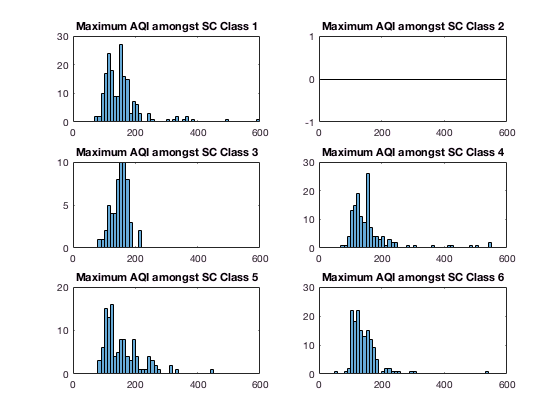

Max_sc1 = MaxAQI(Cases_Spectral_Class==1);
Max_sc2 = MaxAQI(Cases_Spectral_Class==2);
Max_sc3 = MaxAQI(Cases_Spectral_Class==3);
Max_sc4 = MaxAQI(Cases_Spectral_Class==4);
Max_sc5 = MaxAQI(Cases_Spectral_Class==5);
Max_sc6 = MaxAQI(Cases_Spectral_Class==6);
max_edges_sc = [0:10:600];

subplot(3,2,1) 
histogram(Max_sc1, max_edges_sc)
title('Maximum AQI amongst SC Class 1')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,2)
histogram(Max_sc2, max_edges_sc)
title('Maximum AQI amongst SC Class 2')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,3)
histogram(Max_sc3, max_edges_sc)
title('Maximum AQI amongst SC Class 3')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,4) 
histogram(Max_sc4, max_edges_sc)
title('Maximum AQI amongst SC Class 4')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,5)
histogram(Max_sc5, max_edges_sc)
title('Maximum AQI amongst SC Class 5')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,6)
histogram(Max_sc6, max_edges_sc)
title('Maximum AQI amongst SC Class 6')

%xlim([0 90])
%ylim([0 275])


p90_sc1 = per90(Cases_Spectral_Class==1);
p90_sc2 = per90(Cases_Spectral_Class==2);
p90_sc3 = per90(Cases_Spectral_Class==3);
p90_sc4 = per90(Cases_Spectral_Class==4);
p90_sc5 = per90(Cases_Spectral_Class==5);
p90_sc6 = per90(Cases_Spectral_Class==6);
p90_edges_sc = [0:10:100]

p90_edges_sc =      0    10    20    30    40    50    60    70    80    90   100


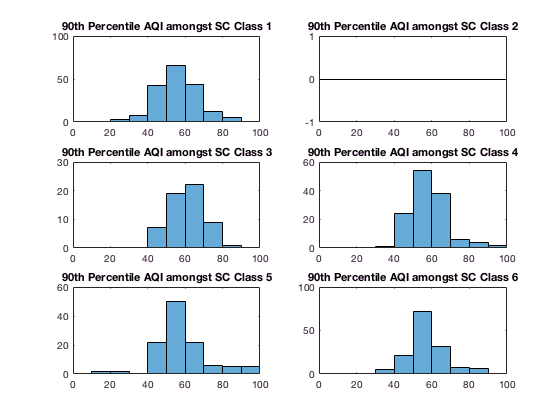


subplot(3,2,1) 
histogram(p90_sc1, p90_edges_sc)
title('90th Percentile AQI amongst SC Class 1')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,2)
histogram(p90_sc2, p90_edges_sc)
title('90th Percentile AQI amongst SC Class 2')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,3)
histogram(p90_sc3, p90_edges_sc)
title('90th Percentile AQI amongst SC Class 3')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,4) 
histogram(p90_sc4, p90_edges_sc)
title('90th Percentile AQI amongst SC Class 4')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,5)
histogram(p90_sc5, p90_edges_sc)
title('90th Percentile AQI amongst SC Class 5')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,6)
histogram(p90_sc6, p90_edges_sc)
title('90th Percentile AQI amongst SC Class 6')

%xlim([0 90])
%ylim([0 275])

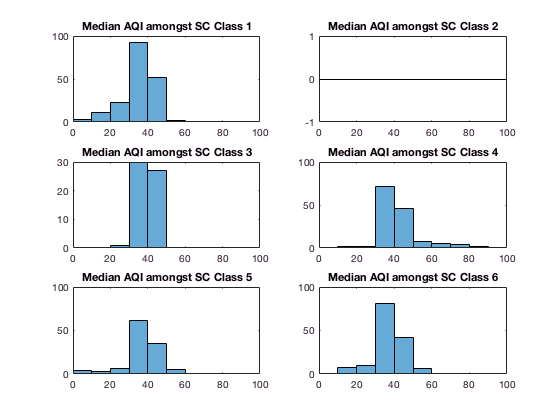

Med_sc1 = MedAQI(Cases_Spectral_Class==1);
Med_sc2 = MedAQI(Cases_Spectral_Class==2);
Med_sc3 = MedAQI(Cases_Spectral_Class==3);
Med_sc4 = MedAQI(Cases_Spectral_Class==4);
Med_sc5 = MedAQI(Cases_Spectral_Class==5);
Med_sc6 = MedAQI(Cases_Spectral_Class==6);
med_edges_sc = [0:10:100];

subplot(3,2,1) 
histogram(Med_sc1, med_edges_sc)
title('Median AQI amongst SC Class 1')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,2)
histogram(Med_sc2, med_edges_sc)
title('Median AQI amongst SC Class 2')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,3)
histogram(Med_sc3, med_edges_sc)
title('Median AQI amongst SC Class 3')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,4) 
histogram(Med_sc4, med_edges_sc)
title('Median AQI amongst SC Class 4')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,5)
histogram(Med_sc5, med_edges_sc)
title('Median AQI amongst SC Class 5')
%xlim([0 90])
%ylim([0 275])

subplot(3,2,6)
histogram(Med_sc6, med_edges_sc)
title('Median AQI amongst SC Class 6')

%xlim([0 90])
%ylim([0 275])